clear
clc
close all

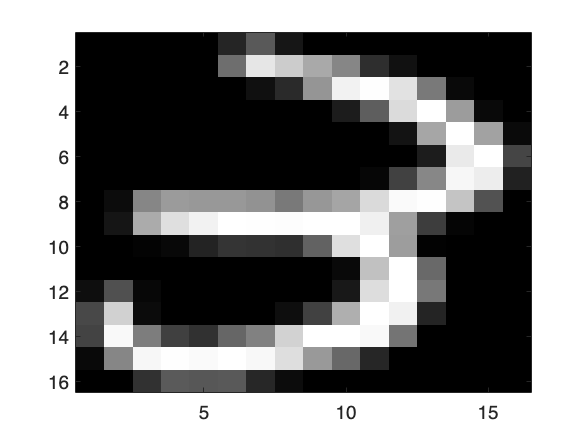

load('Files/threes.mat','-ascii');
image_no=1;
colormap('gray');
imagesc(reshape(threes(image_no,:),16,16),[0,1]);

## Display the average "3"


average = mean(threes,1);
colormap('gray');
imagesc(reshape(average,16,16),[0,1]);

## Plot eigenvalues

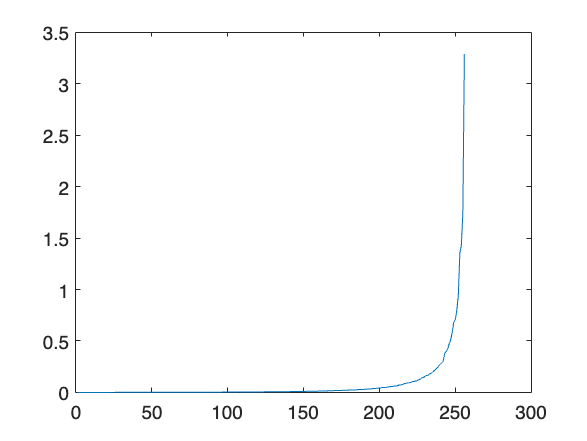


covarianceMatrix = cov(threes);
[eigenvecs,eigenvals] = eig(covarianceMatrix); %Eigenvectors are column vectors in the matrix
eigenvals = diag(eigenvals);
plot(eigenvals);

## use 1-4 pcs(eigen vectors)


zeroMeanD = threes - mean(threes); %Column-wise mean
covarianceMatrix = cov(zeroMeanD);
[eigen_vecs,eigen_vals] = eig(covarianceMatrix); %Eigenvectors are column vectors in the matrix
eigen_vals = diag(eigen_vals);

[eigen_vals, sort_indices] = sort(eigen_vals, 'descend');
eig_vectors = eigen_vecs(:, sort_indices);

zero_reconstructed_data = cell(1, 4);  % 1-4 PCs, 4 500*256 dataset
q = 4; % PC number

for i=1:q
    pc_matrix = eig_vectors(:, 1:i);
    compressed_data = zeroMeanD * pc_matrix;
    reconstructed_data = compressed_data * pc_matrix';
    reconstructed_data = reconstructed_data + mean(threes);
    zero_reconstructed_data{i} = reconstructed_data;

end

## plot 1-4 pcs(eigen vectors) with original for comparison

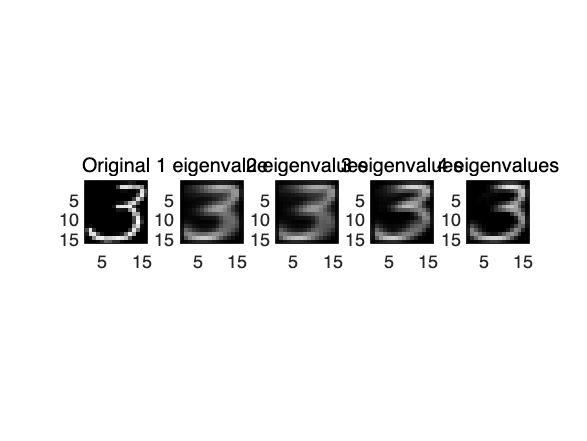


image_no = 100;
figure;
s = subplot(1,5,1);
colormap('gray');
imagesc(reshape(threes(image_no,:),16,16),[0,1]);
title('Original');
axis image;
subplot(1,5,2);
imagesc(reshape(zero_reconstructed_data{1}(image_no,:),16,16),[0,1]);
title('1 eigenvalue');
axis image;
subplot(1,5,3);
imagesc(reshape(zero_reconstructed_data{2}(image_no,:),16,16),[0,1]);
title('2 eigenvalues');
axis image;
subplot(1,5,4);
imagesc(reshape(zero_reconstructed_data{3}(image_no,:),16,16),[0,1]);
title('3 eigenvalues');
axis image;
subplot(1,5,5);
imagesc(reshape(zero_reconstructed_data{4}(image_no,:),16,16),[0,1]);
title('4 eigenvalues');
axis image;

hold off

## sort eigenvalues: compare q = 50 and q = 256

q = 256;

%Initialise errors 
errors = zeros(1,q);

maxQ = size(threes,2);
zeroMeanD = threes - mean(threes); %Column-wise mean

for i=1:q
    covarianceMatrix = cov(zeroMeanD);
    [eigenvecs,eigenvals] = eigs(covarianceMatrix,i); %Eigenvectors are column vectors in the matrix
    eigenvals = diag(eigenvals);

    transformedDataset = eigenvecs.' * zeroMeanD.';

    reconstructedZeroMeanDataset = eigenvecs * transformedDataset;

    reconstructedZeroMeanDataset = reconstructedZeroMeanDataset.';
    reconstructedDataset = reconstructedZeroMeanDataset + mean(threes);

    reconstructionError= sqrt(mean(mean((zeroMeanD-reconstructedZeroMeanDataset).^2))); %Root mean square difference
    %i
    
    
    errors(1,i) = reconstructionError;
end

q = 256;
zeroMeanD = threes - mean(threes); %Column-wise mean
% Compute the covariance matrix
covariance = cov(zeroMeanD);

% Compute the eigenvalues of the covariance matrix
[eigenvectors, eigenvalues] = eig(covariance);

% Extract the diagonal matrix of eigenvalues
eigenvalues = diag(eigenvalues);

% Sort the eigenvalues in descending order
[eigenvalues_sorted, sort_idx] = sort(eigenvalues, 'descend');

% Compute the cumulative sum of the sorted eigenvalues
eigenvalue_cumsum = cumsum(eigenvalues_sorted);

% Compute the sum of all eigenvalues
total_eigenvalue = sum(eigenvalues_sorted);

% Compute the sum of all but the i largest eigenvalues for i = 1 : 256
sum_except_i = total_eigenvalue - eigenvalue_cumsum + eigenvalues_sorted;

% Compute the reconstruction errors for q = 1 : 50

reconstruction_errors = zeros(q, 1);
for i = 1 : q
    % Compute the projection matrix and projection coefficients
    projection_matrix = eigenvectors(:, sort_idx(1:i));
    projection_coefficients = zeroMeanD * projection_matrix;
    
    % Reconstruct the images from the compressed data
    reconstructed_matrix = projection_coefficients * projection_matrix' + mean(threes);
    
    % Compute the reconstruction errors
    reconstruction_errors(i) = norm(threes - reconstructed_matrix, 'fro')^2 / numel(threes);
end

% Compare the first 50 elements of sum_except_i to the vector of reconstruction errors
figure;
plot(1:q, reconstruction_errors(1:q), 'r-');
hold on;
plot(1:q, errors(1:q), 'b-');
legend('Sorted', 'Unsorted');
xlabel('Number of principal components');
ylabel('RMSE');

